# **RS-HL-11: Multi User Sequential Simulation**

**UT Austin Oden Institute**

**Hongseok Kim**

**07/29/2024**

### I. Load the SAT-to-SAT dataset

clear;clc;
% Load the Satellite Contat Dataset
addpath('~/Desktop/Redstone_Project/RS_HL/RS_HL_10_TV_MDP_Functions')
load('/workspace/RS_Dataset/RS_HL_3_dataset.mat')

### II.Destination Setting and Time Index Vector Setting

% Parameter Setting
% time_index_vector = 100:130;
% start_time_index = 100:120;
% state_vector = 1:48;
% 
% start_state = [3,3,3,3];
% destination_state = [38, 38, 38, 38];
% start_time = [100, 100, 100, 100];
% 
% simulation_input = [start_time', start_state', destination_state'];
% number_of_simulation = length(simulation_input(:,1));


time_index_vector = 100:130;
start_time_index = 100:120;
state_vector = 1:48;

number_of_agents = 15;
number_of_destinations = 4;
state_vector = 1:48;


start_state = state_vector(randi(numel(state_vector), 1, number_of_agents));
destination_values = randsample(state_vector,number_of_destinations);
destination_state = destination_values(randi(numel(destination_values), 1, number_of_agents));
start_time = start_time_index(randi(numel(start_time_index), 1, number_of_agents));
simulation_input = [start_time', start_state', destination_state'];
number_of_simulation = length(simulation_input(:,1));

### III. Run the MDP simulation

simulation_result = struct();
MDP = struct();

for simulation_index = 1:number_of_simulation

    if simulation_index == 1
        sat_to_sat_matrix = sat_to_sat_contact_3d_matrix;
    else
        sat_to_sat_matrix = sat_to_sat_matrix_updated;
    end

    % Run the MDP
    MDP.(['MDP',num2str(simulation_index)]) = runMDP(sat_to_sat_matrix, time_index_vector,destination_state(simulation_index)); 
    [time_list, reward_list, state_list, state_value_list]= simulation_test(start_time(simulation_index),start_state(simulation_index), MDP.(['MDP',num2str(simulation_index)]),time_index_vector,destination_state(simulation_index));

    % Record ths simulation result
    simulation_result.(['simulation',num2str(simulation_index)]).result = [time_list,  state_list,reward_list, state_value_list];



    number_of_states = length(state_vector);
    state_value_over_time = zeros(length(time_index_vector),number_of_states);
    for t = 1:length(time_index_vector)
        for state_index = 1:number_of_states
            state_value_over_time(t,state_index) = MDP.(['MDP',num2str(simulation_index)]).(['time' num2str(time_index_vector(t))]).(['state' num2str(state_index)]).('state_value');            
        end
    end

    simulation_result.(['simulation',num2str(simulation_index)]).state_value_over_time = state_value_over_time;


    % Update the sat_to_sat_matrix
    sat_to_sat_matrix_updated = sat_to_sat_matrix;

    for index = 2:length(time_list)

    time_index = time_list(index);
    state_index = state_list(index);

    % sat_to_sat_matrix_updated(state_index,:,time_index) = 0;
    sat_to_sat_matrix_updated(:,state_index,time_index-1) = 0;
    % sat_to_sat_matrix_updated(state_index,state_index,time_index) = 1;

    % sat_to_sat_matrix_updated(state_index,:,time_index+1) = 0;
    % sat_to_sat_matrix_updated(:,state_index,time_index+1) = 0;   
    % sat_to_sat_matrix_updated(state_index,state_index,time_index+1) = 1;
    end  

end

#### III. State Value changing over time

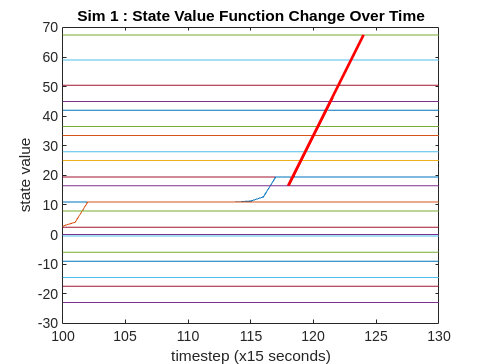

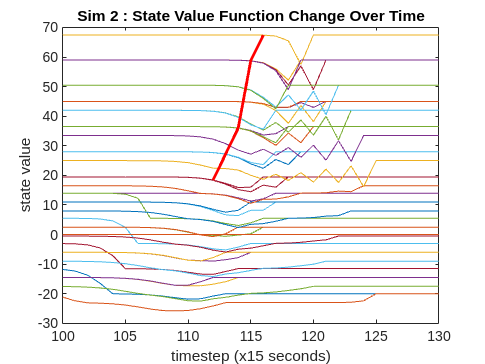

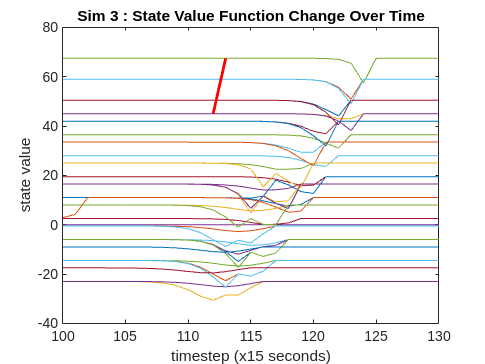

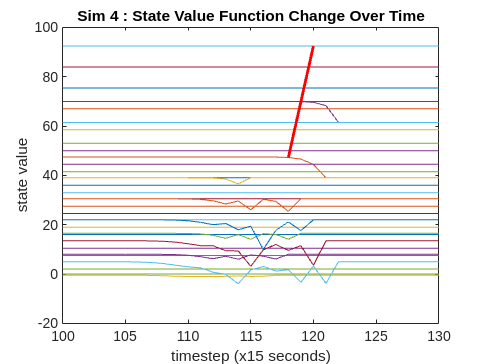

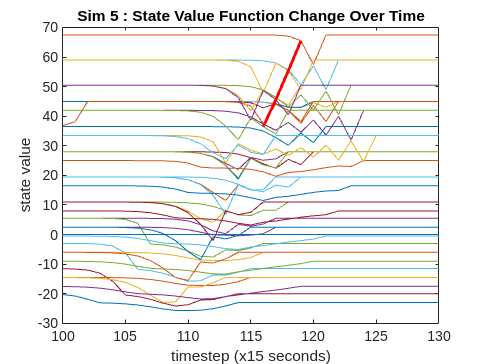

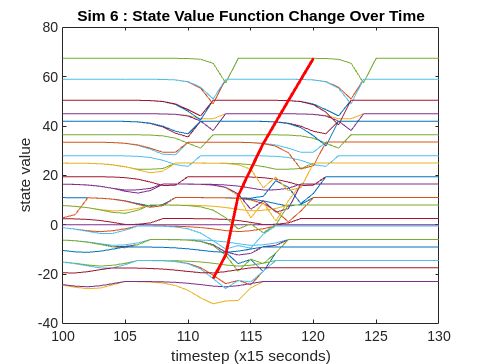

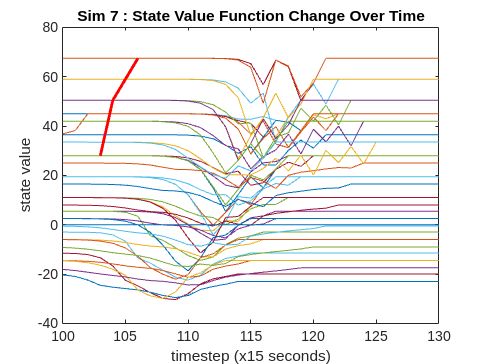

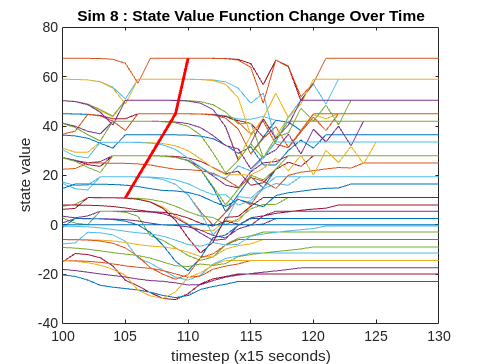

for simulation_index = 1:number_of_simulation

    figure;
    for state_index = 1:number_of_states
        plot(time_index_vector,simulation_result.(['simulation',num2str(simulation_index)]).state_value_over_time(:,state_index))
        hold on
    end

    result = simulation_result.(['simulation',num2str(simulation_index)]).result;
    result = result(result(:,4)~=0,:);
    plot(result(:,1),result(:,4),'r','LineWidth',2)

    hold off
    title(sprintf('Sim %d : State Value Function Change Over Time',simulation_index))
    xlabel('timestep (x15 seconds)')
    ylabel('state value')

end

### IV. State Value By Each Simulation

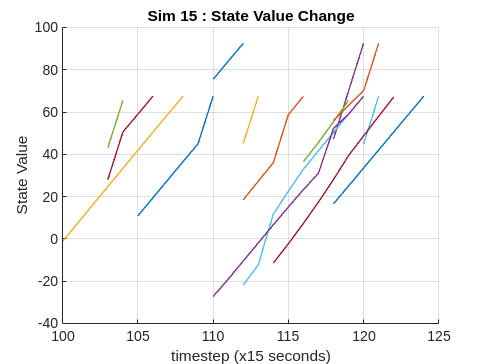

figure;
hold on
for simulation_index = 1:number_of_simulation
    result = simulation_result.(['simulation',num2str(simulation_index)]).result;
    result = result(result(:,4)~=0,:);
    plot(result(:,1),result(:,4),'LineWidth',1,'DisplayName',sprintf('sim %d', simulation_index))
end
hold off
title(sprintf('Sim %d : State Value Change',simulation_index))
grid on
xlabel('timestep (x15 seconds)')
ylabel('State Value')

% legend('show','Location','northwest')

### V. Reward Value By Each Simulation

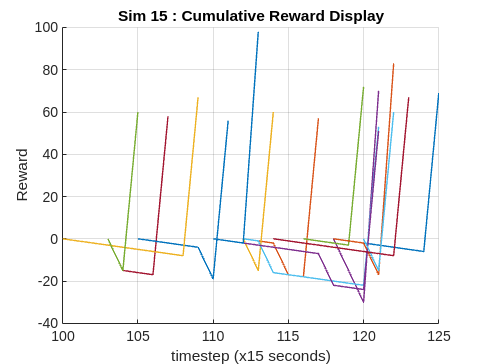

figure;
hold on
for simulation_index = 1:number_of_simulation
    result = simulation_result.(['simulation',num2str(simulation_index)]).result;
    plot(result(:,1),result(:,3),'LineWidth',1,'DisplayName',sprintf('sim %d', simulation_index))
end
hold off
title(sprintf('Sim %d : Cumulative Reward Display',simulation_index))
grid on
xlabel('timestep (x15 seconds)')
ylabel('Reward')

% legend('show','Location','northwest')

### VI. Data Plot on the Network

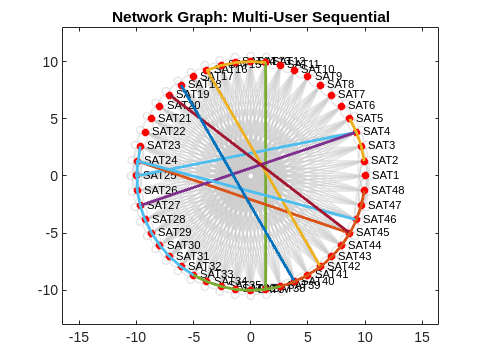

% Number of ground stations and satellites
num_sats = 48;

% Create a graph object
G = graph();

% Load the Satellite Contact Matrix
Sat_to_Sat = sat_to_sat_contact_3d_matrix(:,:,time_index);

% Add Satellites as nodes
for i = 1:num_sats
    G = addnode(G, sprintf('SAT%d', i));
end


% Add edges between Satellites
for i = 1:num_sats
    for j = 1:num_sats
        if Sat_to_Sat(i, j) == 1
            G = addedge(G, sprintf('SAT%d', i), sprintf('SAT%d', j));
        end
    end
end

pi = 3.1415026535;
satellite_radius = 10;

% Satellite positions
satellite_angles = linspace(0, 2*pi, num_sats+1);
satellite_angles = satellite_angles(1:end-1);
satellite_x = satellite_radius * cos(satellite_angles);
satellite_y = satellite_radius * sin(satellite_angles);

% Plot the network graph
figure;
plot(G, 'XData', satellite_x, 'YData', satellite_y, 'NodeColor', [0.6 0.6 0.6], 'EdgeColor', [0.8 0.8 0.8], 'LineWidth', 1,'DisplayName','Networks');
hold on;
% Plot the ground stations in blue and the satellites in red
plot(satellite_x, satellite_y, 'ro', 'MarkerSize', 5, 'MarkerFaceColor', 'r','DisplayName','satellites');

for simulation_index = 1:number_of_simulation

sim_result = simulation_result.(['simulation',num2str(simulation_index)]).result;

Data_Transmission_Sequence = zeros(length(sim_result(:,1)),2);

    for ii = 1:length(sim_result(:,1))
        Data_Transmission_Sequence(ii,:) = [satellite_x(sim_result(ii,2)), satellite_y(sim_result(ii,2))];
    end

    plot(Data_Transmission_Sequence(:,1),Data_Transmission_Sequence(:,2),'LineWidth',2,'DisplayName',sprintf('sim %d', simulation_index));

end


hold off
% legend('show','location','northwest')
% Adjust the axis limits to fit the plot
axis equal;
title('Network Graph: Multi-User Sequential');